clc;
clear;
close all;

Brad = uint8(zeros(80,80,5));

Brad(:,:,1) = rgb2gray(imread("B1img.jpg"));
Brad(:,:,2) = rgb2gray(imread("B2img.jpg"));
Brad(:,:,3) = rgb2gray(imread("B3img.jpg"));
Brad(:,:,4) = rgb2gray(imread("B4img.jpg"));
Brad(:,:,5) = rgb2gray(imread("B5img.jpg"));

Johnny = uint8(zeros(80,80,5));

Johnny(:,:,1) = rgb2gray(imread("J1img.jpg"));
Johnny(:,:,2) = rgb2gray(imread("J2img.png"));
Johnny(:,:,3) = rgb2gray(imread("J3img.jpg"));
Johnny(:,:,4) = rgb2gray(imread("J4img.png"));
Johnny(:,:,5) = rgb2gray(imread("J5img.png"));

Ruben = uint8(zeros(80,80,5));

Ruben(:,:,1) = rgb2gray(imread("R1img.png"));
Ruben(:,:,2) = rgb2gray(imread("R2img.png"));
Ruben(:,:,3) = rgb2gray(imread("R3img.png"));
Ruben(:,:,4) = rgb2gray(imread("R4img.png"));
Ruben(:,:,5) = rgb2gray(imread("R5img.png"));

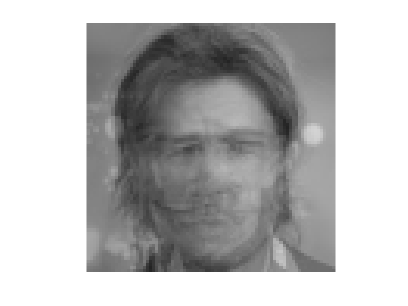

Mbrad=uint8(zeros(80,80));
MJohnny=uint8(zeros(80,80));
MRuben=uint8(zeros(80,80));

for i=1:80
    for j=1:80
        Mbrad(i,j)= mean(Brad(i,j,:));
        MJohnny(i,j)= mean(Johnny(i,j,:));
        MRuben(i,j)= mean(Ruben(i,j,:));
    end
end
imshow(Mbrad)

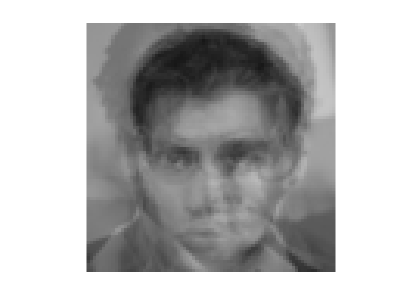

imshow(MJohnny)

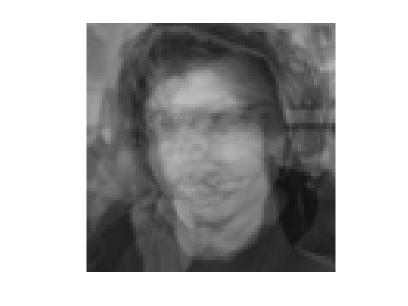

imshow(MRuben)

A = uint8(zeros(15,6400));

A(1,:) = transpose(reshape(transpose(Brad(:,:,1)),[],1));
A(2,:) = transpose(reshape(transpose(Brad(:,:,2)),[],1));
A(3,:) = transpose(reshape(transpose(Brad(:,:,3)),[],1));
A(4,:) = transpose(reshape(transpose(Brad(:,:,4)),[],1));
A(5,:) = transpose(reshape(transpose(Brad(:,:,5)),[],1));

A(6,:) = transpose(reshape(transpose(Johnny(:,:,1)),[],1));
A(7,:) = transpose(reshape(transpose(Johnny(:,:,2)),[],1));
A(8,:) = transpose(reshape(transpose(Johnny(:,:,3)),[],1));
A(9,:) = transpose(reshape(transpose(Johnny(:,:,4)),[],1));
A(10,:) = transpose(reshape(transpose(Johnny(:,:,5)),[],1));

A(11,:) = transpose(reshape(transpose(Ruben(:,:,1)),[],1));
A(12,:) = transpose(reshape(transpose(Ruben(:,:,2)),[],1));
A(13,:) = transpose(reshape(transpose(Ruben(:,:,3)),[],1));
A(14,:) = transpose(reshape(transpose(Ruben(:,:,4)),[],1));
A(15,:) = transpose(reshape(transpose(Ruben(:,:,5)),[],1));

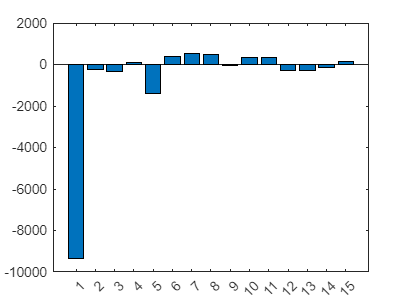

C = double(transpose(A))*double(A);
[V,D] = eigs(C,15);

pbrad = reshape(double(Mbrad),[1,6400])*V;
bar(pbrad)

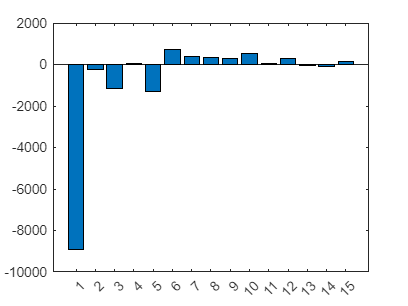

pJohnny = reshape(double(MJohnny),[1,6400])*V;
bar(pJohnny)

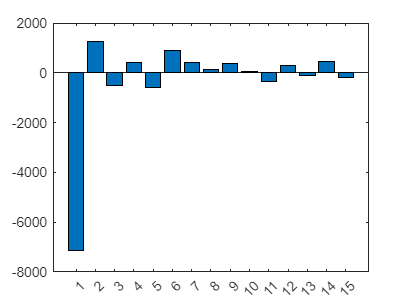

pRuben = reshape(double(MRuben),[1,6400])*V;
bar(pRuben)

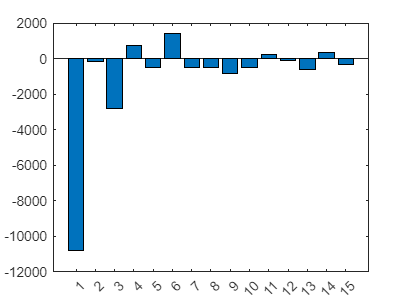

Camilo = rgb2gray(imread("camilo.png"));
Sergio = rgb2gray(imread("sergio.png"));
JuanP = rgb2gray(imread("JuanP.png"));
pCamilo = reshape(double(Camilo),[1,6400])*V;
bar(pCamilo)

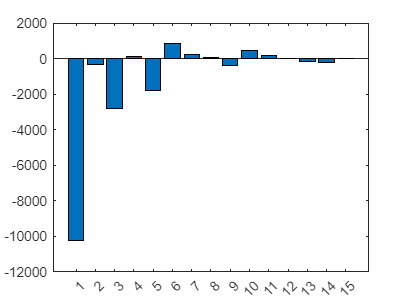

pSergio = reshape(double(Sergio),[1,6400])*V;
bar(pSergio)

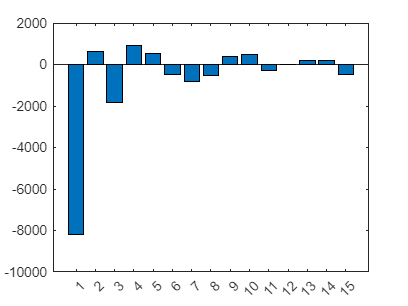

pJuanP = reshape(double(JuanP),[1,6400])*V;
bar(pJuanP)

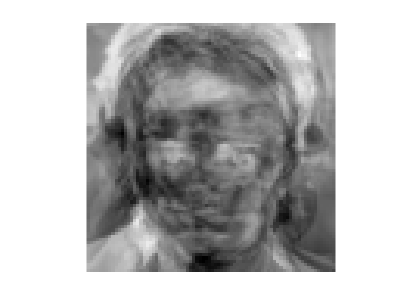

xprimaC = V*transpose(pCamilo);
xrecoC = reshape(xprimaC,[80,80]);
imshow(transpose(xrecoC),[])

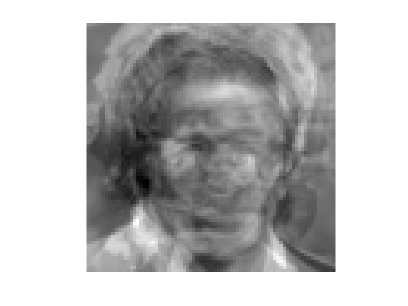


xprimaS = V*transpose(pSergio);
xrecoS = reshape(xprimaS,[80,80]);
imshow(transpose(xrecoS),[])

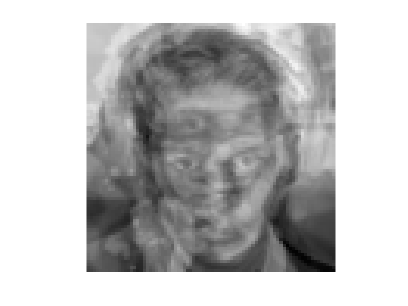


xprimaJ = V*transpose(pJuanP);
xrecoJ = reshape(xprimaJ,[80,80]);
imshow(transpose(xrecoJ),[])

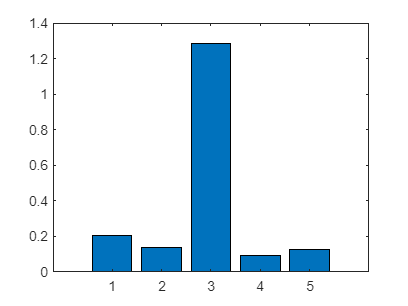

ErrorCamilo = zeros(5,1);
ErrorSergio = zeros(5,1);
ErrorJuanP = zeros(5,1);
for i=1:5
    ojVb = reshape(double(Brad(:,:,i)),[1,6400])*V;
    ErrorCamilo(i) = abs(ojVb-pCamilo)/abs(ojVb);
    ojVj = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorSergio(i) = abs(ojVj-pSergio)/abs(ojVj);
    ojVr = reshape(double(Ruben(:,:,i)),[1,6400])*V;
    ErrorJuanP(i) = abs(ojVr-pJuanP)/abs(ojVr);
end
figure
bar(ErrorCamilo)

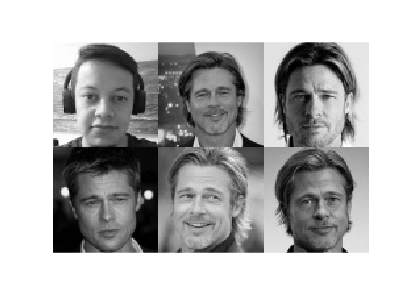

momt1 = cat(3,Camilo,Brad(:,:,1),Brad(:,:,2),Brad(:,:,3),Brad(:,:,4),Brad(:,:,5));
montage(momt1);

mean(ErrorCamilo)

ans = 0.3695

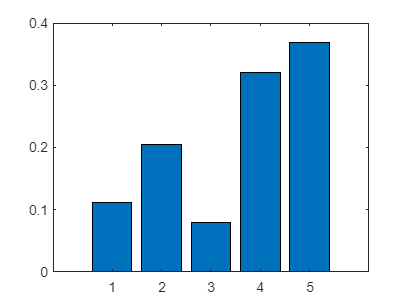

figure
bar(ErrorSergio)

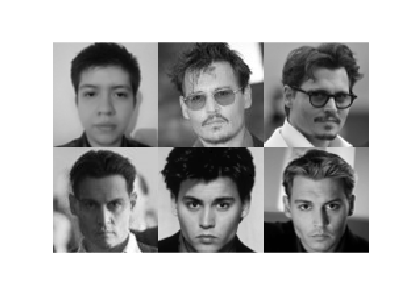

momt2 = cat(3,Sergio,Johnny(:,:,1),Johnny(:,:,2),Johnny(:,:,3),Johnny(:,:,4),Johnny(:,:,5));
montage(momt2);

mean(ErrorSergio)

ans = 0.2169

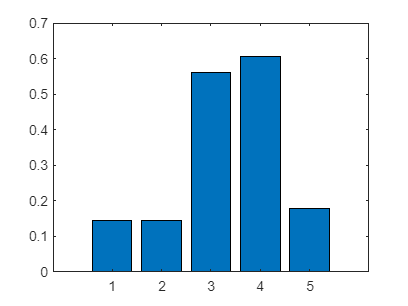

figure
bar(ErrorJuanP)

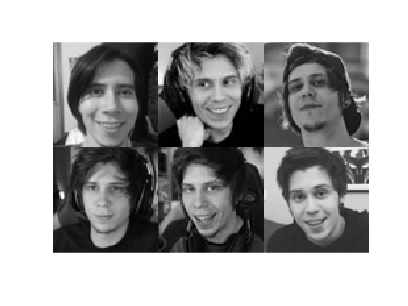

momt2 = cat(3,JuanP,Ruben(:,:,1),Ruben(:,:,2),Ruben(:,:,3),Ruben(:,:,4),Ruben(:,:,5));
montage(momt2);

mean(ErrorJuanP)

ans = 0.3269

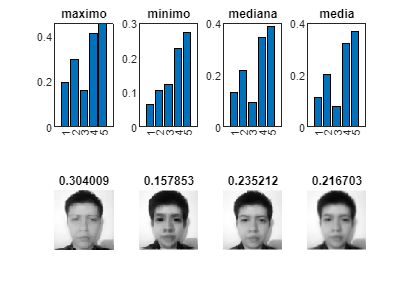

Sergiof1 = FilterMax(Sergio,3);
Sergiof2 = FilterMin(Sergio,3);
Sergiof3 = FilterMedian(Sergio,3);
Sergiof4 = FilterMean(Sergio,3);

pSergiof1 = reshape(double(Sergiof1),[1,6400])*V;
pSergiof2 = reshape(double(Sergiof2),[1,6400])*V;
pSergiof3 = reshape(double(Sergiof3),[1,6400])*V;
pSergiof4 = reshape(double(Sergiof4),[1,6400])*V;

ErrorSergiof1 = zeros(5,1);
ErrorSergiof2 = zeros(5,1);
ErrorSergiof3 = zeros(5,1);
ErrorSergiof4 = zeros(5,1);
for i=1:5
    ojVf1 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorSergiof1(i) = abs(ojVf1-pSergiof1)/abs(ojVf1);
    ojVf2 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorSergiof2(i) = abs(ojVf2-pSergiof2)/abs(ojVf2);
    ojVf3 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorSergiof3(i) = abs(ojVf3-pSergiof3)/abs(ojVf3);
    ojVf4 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorSergiof4(i) = abs(ojVf4-pSergiof4)/abs(ojVf4);
end

figure
subplot(2,4,1)
bar(ErrorSergiof1);title("maximo")
subplot(2,4,2)
bar(ErrorSergiof2);title("minimo")
subplot(2,4,3)
bar(ErrorSergiof3);title("mediana")
subplot(2,4,4)
bar(ErrorSergiof4);title("media")
subplot(2,4,5)
imshow(Sergiof1,[]);title(mean(ErrorSergiof1))
subplot(2,4,6)
imshow(Sergiof2,[]);title(mean(ErrorSergiof2))
subplot(2,4,7)
imshow(Sergiof3,[]);title(mean(ErrorSergiof3))
subplot(2,4,8)
imshow(Sergiof4,[]);title(mean(ErrorSergiof4))

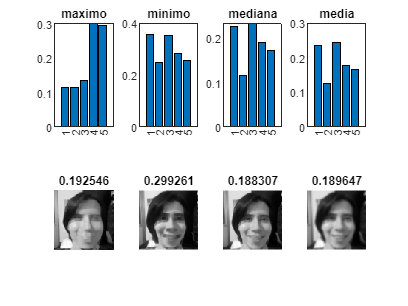

JuanPf1 = FilterMax(JuanP,3);
JuanPf2 = FilterMin(JuanP,3);
JuanPf3 = FilterMedian(JuanP,3);
JuanPf4 = FilterMean(JuanP,3);

pJuanPf1 = reshape(double(JuanPf1),[1,6400])*V;
pJuanPf2 = reshape(double(JuanPf2),[1,6400])*V;
pJuanPf3 = reshape(double(JuanPf3),[1,6400])*V;
pJuanPf4 = reshape(double(JuanPf4),[1,6400])*V;

ErrorJuanPf1 = zeros(5,1);
ErrorJuanPf2 = zeros(5,1);
ErrorJuanPf3 = zeros(5,1);
ErrorJuanPf4 = zeros(5,1);
for i=1:5
    ojVf1 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorJuanPf1(i) = abs(ojVf1-pJuanPf1)/abs(ojVf1);
    ojVf2 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorJuanPf2(i) = abs(ojVf2-pJuanPf2)/abs(ojVf2);
    ojVf3 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorJuanPf3(i) = abs(ojVf3-pJuanPf3)/abs(ojVf3);
    ojVf4 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorJuanPf4(i) = abs(ojVf4-pJuanPf4)/abs(ojVf4);
end

figure
subplot(2,4,1)
bar(ErrorJuanPf1);title("maximo")
subplot(2,4,2)
bar(ErrorJuanPf2);title("minimo")
subplot(2,4,3)
bar(ErrorJuanPf3);title("mediana")
subplot(2,4,4)
bar(ErrorJuanPf4);title("media")
subplot(2,4,5)
imshow(JuanPf1,[]);title(mean(ErrorJuanPf1))
subplot(2,4,6)
imshow(JuanPf2,[]);title(mean(ErrorJuanPf2))
subplot(2,4,7)
imshow(JuanPf3,[]);title(mean(ErrorJuanPf3))
subplot(2,4,8)
imshow(JuanPf4,[]);title(mean(ErrorJuanPf4))

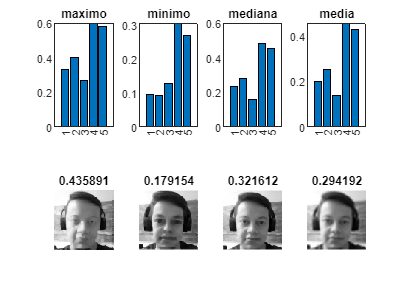

Camilof1 = FilterMax(Camilo,3);
Camilof2 = FilterMin(Camilo,3);
Camilof3 = FilterMedian(Camilo,3);
Camilof4 = FilterMean(Camilo,3);

pCamilof1 = reshape(double(Camilof1),[1,6400])*V;
pCamilof2 = reshape(double(Camilof2),[1,6400])*V;
pCamilof3 = reshape(double(Camilof3),[1,6400])*V;
pCamilof4 = reshape(double(Camilof4),[1,6400])*V;

ErrorCamilof1 = zeros(5,1);
ErrorCamilof2 = zeros(5,1);
ErrorCamilof3 = zeros(5,1);
ErrorCamilof4 = zeros(5,1);
for i=1:5
    ojVf1 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorCamilof1(i) = abs(ojVf1-pCamilof1)/abs(ojVf1);
    ojVf2 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorCamilof2(i) = abs(ojVf2-pCamilof2)/abs(ojVf2);
    ojVf3 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorCamilof3(i) = abs(ojVf3-pCamilof3)/abs(ojVf3);
    ojVf4 = reshape(double(Johnny(:,:,i)),[1,6400])*V;
    ErrorCamilof4(i) = abs(ojVf4-pCamilof4)/abs(ojVf4);
end

figure
subplot(2,4,1)
bar(ErrorCamilof1);title("maximo")
subplot(2,4,2)
bar(ErrorCamilof2);title("minimo")
subplot(2,4,3)
bar(ErrorCamilof3);title("mediana")
subplot(2,4,4)
bar(ErrorCamilof4);title("media")
subplot(2,4,5)
imshow(Camilof1,[]);title(mean(ErrorCamilof1))
subplot(2,4,6)
imshow(Camilof2,[]);title(mean(ErrorCamilof2))
subplot(2,4,7)
imshow(Camilof3,[]);title(mean(ErrorCamilof3))
subplot(2,4,8)
imshow(Camilof4,[]);title(mean(ErrorCamilof4))